# MAE 158 Drag Calculator

#### Shashwat Sparsh

#### ID: 21697442

### `Skin Friction Drag Coeff`

#### Setup

hp_aircraft = 1;
T = 400;
%P = 1;  % via Table A.2
R = 1716;
rho = 0.0008754;

speedSound = sqrt(1.4*R*T)

speedSound = 980.2857

V = [230:1:880]%765;

V =    230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249   250   251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279


M = V/speedSound    % Mach Number

M =     0.2346    0.2356    0.2367    0.2377    0.2387    0.2397    0.2407    0.2418    0.2428    0.2438    0.2448    0.2458    0.2469    0.2479    0.2489    0.2499    0.2509    0.2520    0.2530    0.2540    0.2550    0.2560    0.2571    0.2581    0.2591    0.2601    0.2611    0.2622    0.2632    0.2642    0.2652    0.2662    0.2673    0.2683    0.2693    0.2703    0.2713    0.2724    0.2734    0.2744    0.2754    0.2765    0.2775    0.2785    0.2795    0.2805    0.2816    0.2826    0.2836    0.2846



Sref = 1000;

%CRexp = [];
%K = [];
%Cf = [];
%f = [];

%% Characteristic Lengths
MACexpW = 0;
MACexph = 0;
MACexpv = 0;
Lc = [MACexpW, MACexph, MACexpv, 16.2, 16.8];

%% Ratios
Lf = 119;
Df = 11;
ratios = [0.12, 0.09, 0.09, 0.06, Lf/Df, 5]  % Thickness and Fineness

ratios =     0.1200    0.0900    0.0900    0.0600   10.8182    5.0000


sigma = [0.2, 0.35, 0.8, 1] % Taper

sigma =     0.2000    0.3500    0.8000    1.0000



%% Sexp
Sexpw = 0;  % Defined Later on
Sexp = [Sexpw, 261, 161]

Sexp =      0   261   161



%% Swet
Swet = [0, 0, 0, 117, 0, 455]

Swet =      0     0     0   117     0   455


#### Wing

bW = 93.2;                      % Span
tcW = 0.18;
sweepangleW = 28;               % Sweep Angle
sigmaW = 0.2;                   % Taper Ratio: cT/cR
CRW = 17.8;                     % Root Chord
Coverage_wing = .17;            % Percent Covered
Rfuse = 11/2;

% Getting Swet %
SexpW = (1-Coverage_wing)*Sref;
SwetW = SWET(SexpW);

% Getting Skin Friction Coefficient %
CTW = sigmaW * CRW;
CRexp_wing = CREXP(CRW, CTW, Rfuse, bW);
MACexpW = MAC(CRexp_wing,CTW)

MACexpW = 11.1755

 
RNw = ReynoldsNumber(V, MACexpW);
Cf_w = CF(RNw);

% Getting Form Factor %
Kwing = Kairfoil(tcW, M, sweepangleW)

Kwing = 1.4574


% Calculating f and adding to array %
fwing = F(Kwing, Cf_w, SwetW)

fwing =     7.7750    7.7695    7.7640    7.7586    7.7531    7.7478    7.7424    7.7371    7.7318    7.7265    7.7213    7.7160    7.7108    7.7057    7.7005    7.6954    7.6903    7.6853    7.6802    7.6752    7.6702    7.6653    7.6603    7.6554    7.6505    7.6457    7.6408    7.6360    7.6312    7.6264    7.6217    7.6169    7.6122    7.6075    7.6029    7.5982    7.5936    7.5890    7.5844    7.5798    7.5753    7.5708    7.5663    7.5618    7.5574    7.5529    7.5485    7.5441    7.5397    7.5354


#### Horizontal Tail

SexpH = 261;
tcH = 0.09;
sweepangleH = 31.6;             % Sweep Angle
sigmaH = 0.35;                  % Wing Taper Ratio
CRH = 11.1;                     % Root Chord

% Getting Swet %
SwetH = SWET(SexpH);

% Getting Skin Friction Coefficient %
CTH = sigmaH * CRH;
MACexpH = MAC(CRH,CTH)

MACexpH = 8.0715

 
RNh = ReynoldsNumber(V, MACexpH);
Cf_h = CF(RNh);

% Getting Form Factor %
Khoriztail = Kairfoil(tcH, M, sweepangleH)

Khoriztail = 1.1720


% Calculating f and adding to array %
fhoriztail = F(Khoriztail, Cf_h, SwetH)

fhoriztail =     2.0745    2.0730    2.0715    2.0700    2.0686    2.0671    2.0656    2.0642    2.0627    2.0613    2.0599    2.0585    2.0570    2.0556    2.0542    2.0528    2.0515    2.0501    2.0487    2.0473    2.0460    2.0446    2.0433    2.0419    2.0406    2.0393    2.0380    2.0367    2.0354    2.0341    2.0328    2.0315    2.0302    2.0289    2.0276    2.0264    2.0251    2.0239    2.0226    2.0214    2.0201    2.0189    2.0177    2.0165    2.0153    2.0140    2.0128    2.0116    2.0105    2.0093


#### Vertical Tail

SexpV = 161;
tcV = 0.09;
sweepangleV = 43.5;             % Sweep Angle 
sigmaV = 0.8;                   % Wing Taper Ratio
CRV = 15.5;                     % Root Chord

% Getting Swet %
SwetV = SWET(SexpV);

% Getting Skin Friction Coefficient %
CTV = sigmaV * CRV;
MACexpV = MAC(CRV,CTV)

MACexpV = 14.0074

 
RNv = ReynoldsNumber(V, MACexpV);
Cf_v = CF(RNv);

% Getting Form Factor %
Kverttail = Kairfoil(tcV, M, sweepangleV)

Kverttail = 1.1354


% Calculating f and adding to array %
fverttail = F(Kverttail, Cf_v, SwetV)

fverttail =     1.1328    1.1320    1.1312    1.1305    1.1297    1.1289    1.1281    1.1274    1.1266    1.1259    1.1251    1.1244    1.1236    1.1229    1.1221    1.1214    1.1207    1.1199    1.1192    1.1185    1.1178    1.1171    1.1164    1.1156    1.1149    1.1142    1.1135    1.1129    1.1122    1.1115    1.1108    1.1101    1.1094    1.1088    1.1081    1.1074    1.1068    1.1061    1.1054    1.1048    1.1041    1.1035    1.1028    1.1022    1.1016    1.1009    1.1003    1.0996    1.0990    1.0984


#### Pylons

SwetP = 117;                    % Wetted Area
tcP = 0.06;
sweepangleP = 0;                % Sweep Angle
sigmaP = 1;                     % Taper Ratio: cT/cR
chordP = 16.2;                  % Chord

% Getting Skin Friction Coefficient %
RNp = ReynoldsNumber(V, chordP);
Cf_p = CF(RNp);

% Getting Form Factor %
Kpylon = Kairfoil(tcP, M, sweepangleP)

Kpylon = 1.1514


% Calculating f and adding to array %
fpylon = F(Kpylon, Cf_p, SwetP)

fpylon =     0.3998    0.3995    0.3993    0.3990    0.3987    0.3985    0.3982    0.3979    0.3976    0.3974    0.3971    0.3969    0.3966    0.3963    0.3961    0.3958    0.3956    0.3953    0.3951    0.3948    0.3946    0.3943    0.3941    0.3938    0.3936    0.3933    0.3931    0.3928    0.3926    0.3924    0.3921    0.3919    0.3916    0.3914    0.3912    0.3909    0.3907    0.3905    0.3902    0.3900    0.3898    0.3896    0.3893    0.3891    0.3889    0.3887    0.3884    0.3882    0.3880    0.3878


#### Fuselage

Lf = 105;
Df = 11;

% Calculating Swet %
SwetF = 0.8 * pi * Df * Lf;

% Getting Skin Friction Coefficient %
RNf = ReynoldsNumber(V, Lf);
Cf_f = CF(RNf)

Cf_f =     0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022



% Getting Form Factor %
ratioF = Lf/Df

ratioF = 9.5455

Kfuse = KFR(ratioF);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
ffuselage = F(Kfuse, Cf_f, SwetF)

ffuselage =     7.1882    7.1837    7.1793    7.1749    7.1705    7.1662    7.1618    7.1575    7.1532    7.1489    7.1447    7.1404    7.1362    7.1320    7.1279    7.1237    7.1196    7.1155    7.1114    7.1073    7.1033    7.0993    7.0952    7.0912    7.0873    7.0833    7.0794    7.0755    7.0716    7.0677    7.0638    7.0600    7.0561    7.0523    7.0485    7.0448    7.0410    7.0373    7.0335    7.0298    7.0261    7.0225    7.0188    7.0152    7.0115    7.0079    7.0043    7.0007    6.9972    6.9936


#### Nacelles

% Swet %
SwetN = 455;

% Getting Skin Friction Coefficient %
Ln = 16.8

Ln = 16.8000

RNn = ReynoldsNumber(V, 16.8);
Cf_n = CF(RNn)

Cf_n =     0.0030    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029



% Getting Form Factor %
ratioN = 5;
Knacelle = KFR(ratioN);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
fnacelle = F(Knacelle, Cf_n, SwetN)

fnacelle =     1.7339    1.7327    1.7315    1.7304    1.7292    1.7280    1.7268    1.7257    1.7245    1.7234    1.7222    1.7211    1.7200    1.7189    1.7177    1.7166    1.7155    1.7144    1.7133    1.7122    1.7111    1.7101    1.7090    1.7079    1.7069    1.7058    1.7047    1.7037    1.7027    1.7016    1.7006    1.6995    1.6985    1.6975    1.6965    1.6955    1.6945    1.6935    1.6925    1.6915    1.6905    1.6895    1.6885    1.6876    1.6866    1.6856    1.6847    1.6837    1.6827    1.6818


#### Total Skin Friction

ftotal = fwing + fhoriztail + fverttail + fpylon + ffuselage + fnacelle;
CDP_total = ftotal./Sref

CDP_total =     0.0203    0.0203    0.0203    0.0203    0.0202    0.0202    0.0202    0.0202    0.0202    0.0202    0.0202    0.0202    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0199    0.0198    0.0198    0.0198    0.0198    0.0198    0.0198    0.0198    0.0198    0.0198    0.0197    0.0197    0.0197    0.0197


### `Induced Drag Coeff`

% Getting CL %
W = 98000;              % Aircraft Weight
q = 0.5 * rho * (V.^2);  % Dynamic Pressure
CL = W ./ (q * Sref)     % Coeff of Lift

CL =     4.2325    4.1959    4.1598    4.1242    4.0890    4.0543    4.0200    3.9861    3.9527    3.9197    3.8871    3.8549    3.8231    3.7917    3.7607    3.7301    3.6998    3.6699    3.6404    3.6112    3.5824    3.5539    3.5257    3.4979    3.4704    3.4433    3.4164    3.3899    3.3636    3.3377    3.3121    3.2868    3.2617    3.2370    3.2125    3.1883    3.1644    3.1407    3.1173    3.0942    3.0713    3.0487    3.0263    3.0042    2.9823    2.9606    2.9392    2.9180    2.8971    2.8763



% Getting Aspect Ratio %
ARw = (bW^2)/Sref

ARw = 8.6862


% Getting CDi %
e = 1;                          % Oswald Efficiency Factor
CDi = (CL.^2) / (pi * ARw * e)   % Coeff of Induced Drag

CDi =     0.6565    0.6452    0.6341    0.6233    0.6127    0.6023    0.5922    0.5823    0.5725    0.5630    0.5537    0.5446    0.5356    0.5269    0.5183    0.5099    0.5016    0.4935    0.4856    0.4779    0.4703    0.4628    0.4555    0.4484    0.4413    0.4345    0.4277    0.4211    0.4146    0.4082    0.4020    0.3959    0.3899    0.3840    0.3782    0.3725    0.3669    0.3615    0.3561    0.3508    0.3457    0.3406    0.3356    0.3307    0.3259    0.3212    0.3166    0.3120    0.3076    0.3032


## `Total Drag & Lift/Drag Ratio`

ProfileDrag = CDP_total .* q .* Sref

ProfileDrag = 	1.0e+03 *

    0.4701    0.4739    0.4777    0.4815    0.4853    0.4892    0.4930    0.4969    0.5007    0.5046    0.5085    0.5124    0.5164    0.5203    0.5243    0.5282    0.5322    0.5362    0.5402    0.5443    0.5483    0.5524    0.5564    0.5605    0.5646    0.5687    0.5728    0.5770    0.5811    0.5853    0.5895    0.5936    0.5978    0.6021    0.6063    0.6105    0.6148    0.6191    0.6234    0.6277    0.6320    0.6363    0.6406    0.6450    0.6494    0.6537    0.6581    0.6626    0.6670    0.6714


InducedDrag = CDi .* q .* Sref

InducedDrag = 	1.0e+04 *

    1.5200    1.5068    1.4939    1.4811    1.4685    1.4560    1.4437    1.4315    1.4195    1.4077    1.3960    1.3844    1.3730    1.3617    1.3506    1.3396    1.3287    1.3180    1.3073    1.2969    1.2865    1.2763    1.2662    1.2562    1.2463    1.2366    1.2269    1.2174    1.2080    1.1987    1.1895    1.1804    1.1714    1.1625    1.1537    1.1450    1.1364    1.1279    1.1195    1.1112    1.1030    1.0949    1.0868    1.0789    1.0710    1.0632    1.0555    1.0479    1.0404    1.0330


CDtotal = CDP_total + CDi

CDtotal =     0.6768    0.6655    0.6544    0.6436    0.6330    0.6226    0.6124    0.6025    0.5927    0.5832    0.5739    0.5647    0.5558    0.5470    0.5384    0.5300    0.5217    0.5136    0.5057    0.4979    0.4903    0.4829    0.4755    0.4684    0.4613    0.4544    0.4477    0.4411    0.4346    0.4282    0.4219    0.4158    0.4098    0.4039    0.3981    0.3924    0.3868    0.3813    0.3759    0.3707    0.3655    0.3604    0.3554    0.3505    0.3457    0.3410    0.3363    0.3318    0.3273    0.3229


TotalDrag = CDtotal .* q .* Sref

TotalDrag = 	1.0e+04 *

    1.5670    1.5542    1.5417    1.5292    1.5170    1.5049    1.4930    1.4812    1.4696    1.4581    1.4468    1.4356    1.4246    1.4137    1.4030    1.3924    1.3819    1.3716    1.3614    1.3513    1.3413    1.3315    1.3218    1.3122    1.3028    1.2934    1.2842    1.2751    1.2661    1.2572    1.2484    1.2397    1.2311    1.2227    1.2143    1.2060    1.1979    1.1898    1.1818    1.1740    1.1662    1.1585    1.1509    1.1434    1.1359    1.1286    1.1214    1.1142    1.1071    1.1001


L = W

L = 98000

LiftToDrag = L ./ TotalDrag

LiftToDrag =     6.2540    6.3053    6.3568    6.4084    6.4602    6.5120    6.5641    6.6162    6.6685    6.7210    6.7735    6.8262    6.8791    6.9320    6.9851    7.0383    7.0916    7.1451    7.1986    7.2523    7.3061    7.3600    7.4141    7.4682    7.5224    7.5768    7.6312    7.6858    7.7404    7.7952    7.8501    7.9050    7.9601    8.0152    8.0704    8.1257    8.1811    8.2366    8.2922    8.3478    8.4035    8.4593    8.5152    8.5712    8.6272    8.6833    8.7394    8.7956    8.8519    8.9082


[LiftToDragMax, index] = max(LiftToDrag);
Voptimum = V(index)

Voptimum = 579

## `Plots`

plot(V, ProfileDrag, 'g', V, InducedDrag, 'b', V, TotalDrag, 'r')
grid on
title("Drag vs Velocity")
ylabel("Drag (lbs)")
xlabel("Velocity: (^{ft}/_{s})")
legend("Profile Drag", "Induced Drag", "Total Drag")
hold off

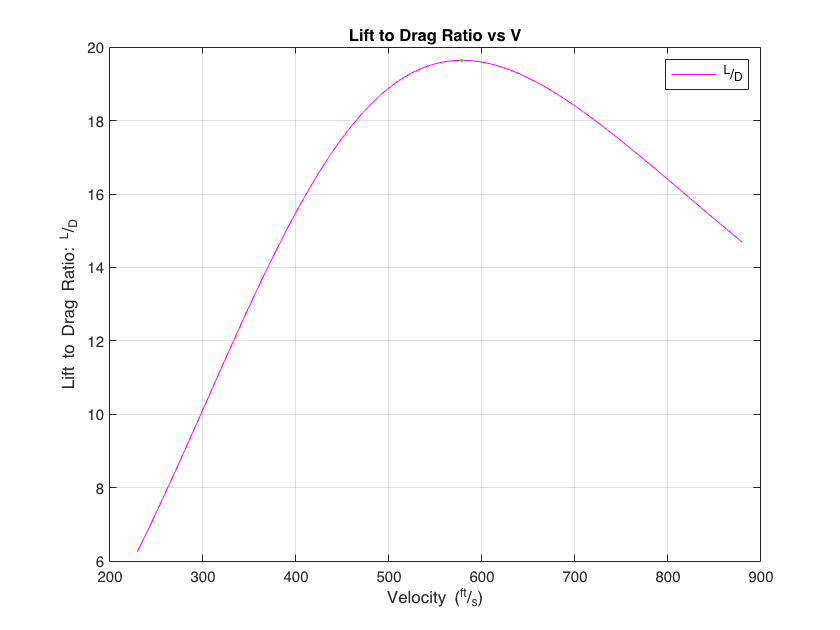


plot(V,LiftToDrag, 'm')
hold on
plot(Voptimum, LiftToDragMax, 'Color', 'g', 'Marker','.', 'LineWidth',1)
grid on
title("Lift to Drag Ratio vs V")
ylabel("Lift to Drag Ratio: ^{L}/_{D}")
xlabel("Velocity (^{ft}/_{s})")
legend("^{L}/_{D}")
hold off;

## `Functions`

#### Reynolds Number Function

function RN = ReynoldsNumber(Velocity, characteristicLength)
    mu = 3.025E-7;
    rho = 0.0008754;
    V = Velocity;
    Lc = characteristicLength;
    RN = (rho * V * Lc)/mu;
end

#### Swet Function

function Swet = SWET(Sexp)
    Swet = 2 * 1.02 * Sexp;
end

#### MAC Function

function cbar = MAC(cR, cT)
    cbar= (2/3) * (cR + cT - ((cR*cT)/(cR+cT)));
end

#### CR Exposed Function

function crexp = CREXP(cR, cT, y, b)
    crexp = cR - ((cR- cT)*(2*(y/b)));
end

#### Skin Friction Coefficient

function Cf = CF(RN)
    Cf = 0.455 ./ ((log10(RN)).^2.58);
end

#### Form Factor for Airfoils

function K = Kairfoil(tc, Mo, sweepAngle)
    numTerm = (2-Mo.^2) * cosd(sweepAngle);
    denTerm = sqrt(1-(Mo*cosd(sweepAngle)^2));
    Z = numTerm/denTerm;
    K = 1 + (Z * tc) + (100*tc^4);
end

#### Form Factor via Fineness Ratio

function K = KFR(LbyD)
    K = 1.991*LbyD^-1.024+0.9084;
    % General model Power2:
    % Coefficients (with 95% confidence bounds):
    %    a =       1.991  (1.882, 2.101)
    %    b =      -1.024  (-1.091, -0.9582)
    %    c =      0.9084  (0.8888, 0.9279)
end

#### F Function

function f = F(K, Cf, Swet)
    f = K * Cf * Swet;
end